# Cargar información de NDVI

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*

%clearvars -except area_estudio;
clear;
close all;

disp(">>> Declarando variables...ok")

>>> Declarando variables...ok



%directorio de datos
dir_data = "D:\DATA\";

% % %Ventana para el mapa region hidrografica rio panuco
% % lon_mapa = [-101.6 -97.40];
% % lat_mapa = [ 18.7  24.3];
% % 
%cuadrante de inicio y tamaño del area de estudio
coord_1k_v6_inicio = [684 724];
coord_1k_v6_tam = [473 476];

%h08v06
coord_1k_v7_inicio = [684 0];
coord_1k_v7_tam = [473 115];

ndvi_tam = [473 591];


## Obtener información de la lista de archivos de datos

info_hdf = f_infohdfs2table(dir_data,'MOD13A2');

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos



[num_registros,~] = size(info_hdf);

if (num_registros > 0)
    % Obtener matrices de latitud y longitud
    [lat,lon,ndvi] = f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


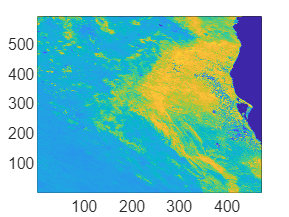


pcolor(ndvi'); shading interp;